 **Task 1: Change cell voltage to 4.2V and recalculate power**

% Updated battery voltage
voltage = 4.2;         % new voltage
current = 2.5;         % keep current same

% Recalculate power
power = voltage * current;
disp("New Power Output (W):")

New Power Output (W):


disp(power)

   10.5000



**Task 2: Increase discharge current to 3A and see new SoC**

capacity = 2.5;             % in Ah
discharge_time = 0.5;       % 0.5 hours
current = 3;                % increased from 2.5 to 3 A

% Calculate new SoC drop
soc_drop = (discharge_time * current) / capacity * 100;
remaining_soc = 100 - soc_drop;

fprintf("Remaining SoC at 3A: %.2f%%\n", remaining_soc)

Remaining SoC at 3A: 40.00%


**Task 3: Plot for 60 minutes instead of 30 minutes**

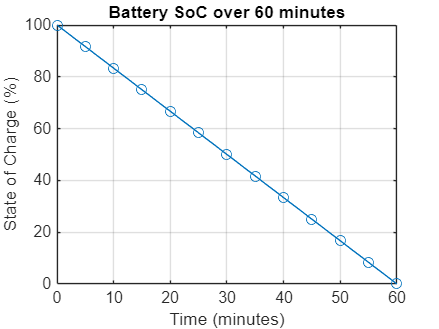

time = 0:5:60;   % 0 to 60 minutes in 5-min steps
capacity = 2.5;
current = 2.5;

% SoC profile over 1 hour
soc = 100 - (time / 60) * (current / capacity * 100);

plot(time, soc, '-o')
xlabel('Time (minutes)')
ylabel('State of Charge (%)')
title('Battery SoC over 60 minutes')
grid on

**Task 4: Add a second cell and compute total pack power**

% 2 cells in series: voltage adds
voltage = 3.7 + 3.7;    % = 7.4 V
current = 2.5;          % same current in series

% Total power of pack
total_power = voltage * current;
fprintf("Total Power of 2-cell series pack: %.2f W\n", total_power)

Total Power of 2-cell series pack: 18.50 W



%Alternatively, for parallel connection:
voltage = 3.7;            % same voltage
current = 2.5 + 2.5;      % current adds
total_power = voltage * current;

